# EE 451 Final Notes!

# Lisa Jacklin

## Walk Throughs/Notes

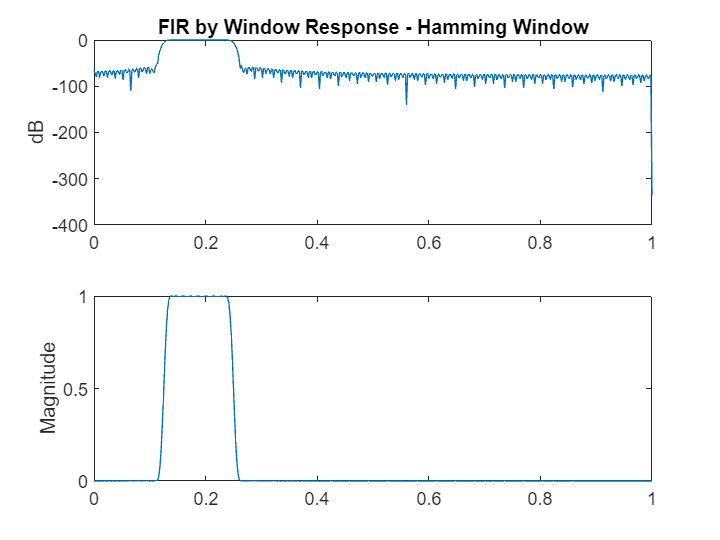

% x_a is bandlimited to 1000 Hz. Minimum sampling frequency is 2000 Hz
% double that is 4000 Hz
%
% Fs = 4000
% Fs/2 = 2000 is mapped to pi
%
% 1 kHz is mapped to pi/2
% 500 Hz is mapped to pi/4
% 250 Hz is mapped to pi/8

% Decimation by 4 will "expand" the occupied bandwidth by the signal
% pi/2 will become 2*pi
% pi/4 will become pi
% pi/8 will become pi/2
%
% If we want to keep only the frequencies of interest, we must
% use a bandpass filter, between pi/8 (0.125pi) to pi/4 (0.25pi)

% so to create the bandpass, we should have ideal_lp(pi/4, M) -
% ideal_lp(pi/8)
% The length of the filter can be estimated via the transition width
% of pi/50. 
% From presentation 17, slide 26, we can use
% M = 8 * pi/(pi/50) = 400

M = 400; %this is the first testing M value we used
M = 296; % this lower value meets the spec and was adjusted based off the M above.

wc2 = pi/4; %first cuttoff value
wc1 = pi/8; %second cutoff value.
%the difference between these is delta w, which is range of the filter.

df = 0.02*pi;

%now, with the values above we can build the ideal low pass as our base
hd = ideal_lp(wc2,M) - ideal_lp(wc1, M);
hm = hamming(M)';%and the hamming window for the filtering we desire based on the signal length
h = hd .* hm; %this will give us what we want to filter through (multiply both together)

%now, we can push through here and display all the additional items
%required to get an accurate view of the function we just built.
[db,mag,pha,grd,w] = freqz_m(h,[1]);
delta_w = 2*pi/1000;

figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('FIR by Window Response - Hamming Window')

subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')


%now, we need to convert this into the s domain. This is required to obtain
%estimations on attenuation
ws1 = wc1 - (df/2);
ws2 = wc2 + (df/2);
filter_length = M;

filter_length = 296

As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 57

As2 = -round(max(db(ws2/delta_w+1:1:501))) % Min Stopband attenuation for second stopband

As2 = 40

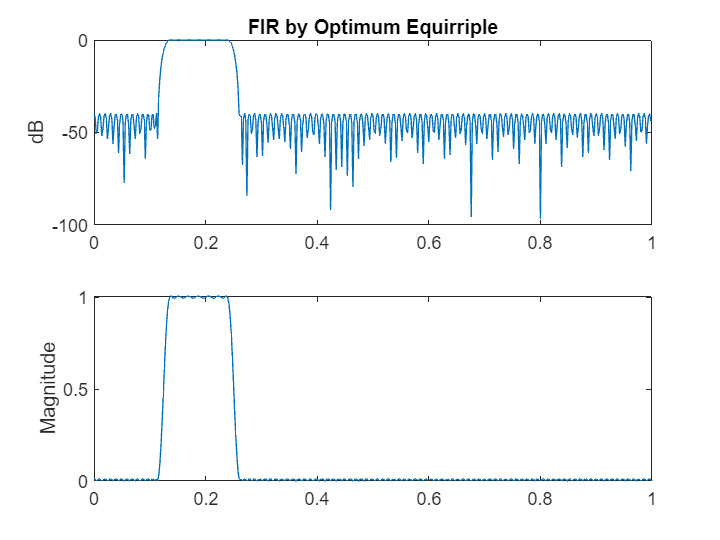

% the attenuation meets the specs

% If we want to use optimum equirripple design, we can use a value of Rp =
% 1 dB
Rp = 0.1; %since this is not given, we are assuming here
As = 40;
%now we can calculate out the passbands for each end
wp1 = wc1 + (df/2);
wp2 = wc2 - (df/2);
f = [ ws1 wp1 wp2 ws2 ] ./ pi; %the frequency range
a = [0 1 0]; %and where the ranges are (low high low in this case)

d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
d = [d2 d1 d2];

[M, fo, ao, W] = firpmord(f,a,d);
h = firpm(M, fo, ao, W);
[db, mag, pha, grd, w] = freqz_m(h,[1]);

figure;
subplot(2,1,1);
plot(w/pi,db);
ylabel('dB');
title('FIR by Optimum Equirriple')

subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

filter_length = M

filter_length = 211

As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 40

As2 = -round(max(db(ws2/delta_w+1:1:501))) % Min Stopband attenuation for second stopband

As2 = 40

## Helpful Links

[https://www.mathworks.com/help/signal/ug/fir-filter-design.html](https://www.mathworks.com/help/signal/ug/fir-filter-design.html)

## Helpful Functions

function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end


## Helpful Screenshots/Tables